# Medium perturbation for base eGEM model

**Author**: Scott Campit

## Summary

This module computes metabolic fluxes for each demand reaction from the unconstrained eGEM model to evaluate how it performs without any other omics data imposed on it.

% Initialize metabolic modeling components
clear all;
initCobraToolbox; changeCobraSolver('gurobi', 'all');



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.25.4).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

## Load necessary variables and set necessary constraints

First let's load some old variables. 

load 07082020.mat; % Latest version of eGEM
load supplementary_software_code ...
    labels media_exchange1 mediareactions1;

% Set up objective function
eGEM.c = zeros(size(eGEM.c));
eGEM.c(string(eGEM.rxns) == 'biomass_objective') = 1;

% Update BiGG exchange reaction notation 
mediareactions1 = strrep(mediareactions1, '(', '_');
mediareactions1 = strrep(mediareactions1, ')', '');

I want to see how medium perturbation impacts flux through several demand reactions.

% Get list of demand reactions from eGEMM
pos = [3770, 3771, 3773:3814];
dm_reactions = string(eGEM.rxns(pos))'

dm_reactions = 1×44 string array
  Columns 1 through 4

    "DM_bulk_methylation"    "DM_bulk_acetylation"    "DM_KACn"    "DM_KACc"

  Columns 5 through 9

    "DM_KMe1"    "DM_KMe2"    "DM_KMe3"    "DM_dna5mtc_n"    "DM_atp_c"

  Columns 10 through 13

    "DM_h3k4me1_n"    "DM_h3k4me2_n"    "DM_h3k4me3_n"    "DM_h3k4ac1_n"

  Columns 14 through 17

    "DM_h3k9me1_n"    "DM_h3k9me2_n"    "DM_h3k9me3_n"    "DM_h3k9ac1_n"

  Columns 18 through 21

    "DM_h3k27me1_n"    "DM_h3k27me2_n"    "DM_h3k27me3_n"    "DM_h3k27ac1_n"

  Columns 22 through 25

    "DM_h3k36me1_n"    "DM_h3k36me2_n"    "DM_h3k36me3_n"    "DM_h3k36ac1_n"

  Columns 26 through 29

    "DM_h3k79me1_n"    "DM_h3k79me2_n"    "DM_h3k79me3_n"    "DM_h3k79ac1_n"

  Columns 30 through 34

    "DM_peplys_n"    "DM_oaa_n"    "DM_cit_n"    "DM_met_n"    "DM_succ_n"

  Columns 35 through 39

    "DM_fum_n"    "DM_akg_n"    "DM_mal__L_n"    "DM_pyr_n"    "DM_ac_n"

  Columns 40 through 44

    "DM_fald_n"    "DM_amet_n"    "DM_

Overall, just set methionine exchange to be really small, instead of -1000.

% Set methionine lower bound to a really small number
[~, pos] = ismember({'EX_met_L_e'}, eGEM.rxns);
eGEM.lb(pos) = -0.005;

We'll also set the objective coefficient value for the demand reaction epsilon to be a really small number. 

This is a parameter that needs to be sampled and studied later for robustness.

epsilon = 1E-3;

Finally, let's set the parameters for `CFR` here.

% Params for constrain flux regulation. Set all to empty.
onreactions = {};     offreactions = {};
hyperparams.eps = []; hyperparams.mode = [];
hyperparams.kap = []; hyperparams.eps2 = [];
hyperparams.rho = []; hyperparams.pfba = false;
hyperparams.kap2 = [];

## Nutrient perturbation with the base metabolic model

These nested `for` loops computes the metabolic fluxes from medium supplementation and deprivation for each demand reaction. 

The final size of this matrix should be `50x44` for 50 metabolites by 44 demand reactions.

% Demand reaction layer
for r = 1:length(dm_reactions)
    [~, rxnPos] = ismember(dm_reactions(r), eGEM.rxns);
    
    % Supplementation / deprivation layer
    for kappatype = 1:2
        if kappatype == 1 % 1 = supplementation
            kappa  = 10; 
        else              % 2 = deprivation
            kappa = 0.01;
        end 
        
        % Nutrient perturbation layer
        for i = 1:50
            mod_kap = kappa;
            if (kappatype == 2) & (ismember(i,[2, 3, 5:19])) % Trace elements
                mod_kap = kappa / 100;
            elseif (kappatype == 1) & (ismember(i, [1;4]))   % Glucose / Glutamine
                mod_kap = 3;
            end
            
            tmp = eGEM;
            tmp.c(rxnPos) = epsilon;
            
            % Modify uptake rate based on supplementation or deprivation
            [~, pos]  = ismember(mediareactions1(i), tmp.rxns);
            tmp.lb(pos) = -media_exchange1(i, 1) * mod_kap;
    
            % Linear optimization
            [~, solution] = CFR(tmp, hyperparams, ...
                                onreactions, offreactions);
            
            % Save based on supplementation / deprivation
            if kappatype == 1
                supplementation(i, r) = solution.x(rxnPos);
                supplementation_grate(i, r) = solution.x(3743);
            else
               deprivation(i, r) = solution.x(rxnPos);
                deprivation_grate(i, r) = solution.x(3743);
            end
        end
    end
end

## Visualize the results from nutrient supplementation and deprivation using heatmaps

We'll make the redbluecmap continuous.

% Colormap
redbluecmap = imresize(redbluecmap, [1000, 3]); 
redbluecmap = min(max(redbluecmap, 0), 1);

Next, we'll set up the labels for the axes

% Set labels
dm_labels = strrep(dm_reactions, '_', ' ');
dm_labels = strrep(dm_labels, 'DM', '');

load unique_nutrients.mat
medium = labels;

The peplys demand reaction was not really informative. So we'll just remove it.

% Find position of peplys reaction
peplys_pos = (dm_reactions == 'DM_peplys_n');
dm_labels(peplys_pos) = [];

% Remove peplys demand reaction
supplementation(:, peplys_pos) = []; supplementation_grate(:, peplys_pos) = [];
deprivation(:, peplys_pos) = [];     deprivation_grate(:, peplys_pos) = [];

We'll set fluxes that are equal to 0 to be NaN for visualization purposes.

% Make some reactions black for none
supplementation(supplementation == 0) = NaN; 
supplementation_grate(supplementation_grate == 0) = NaN;
deprivation(deprivation == 0) = NaN;         
deprivation_grate(deprivation_grate == 0) = NaN;

### Metabolic flux heatmap

Finally, we can construct the two heatmaps side-by-side, where the left one is nutrient supplementation and the right one is nutrient deprivation.

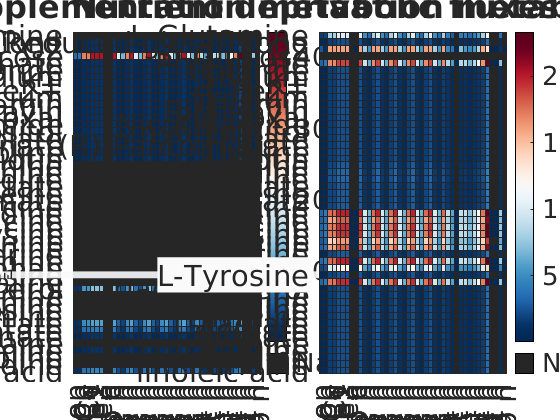

figure;
% Nutrient supplementation heatmap
subplot(1, 2, 1);
heatmap(supplementation, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient supplementation metabolic fluxes', ...
        'FontSize', 22, ...
        'FontName', 'Helvetica');

% Nutrient deprivation heatmap 
subplot(1, 2, 2);
heatmap(deprivation, ...
        'YData', medium, ...
        'XData', dm_labels', ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient deprivation metabolic fluxes', ...
        'FontSize', 22, ...
        'FontName', 'Helvetica');

### Growth rate heatmap

Finally, we can construct the two heatmaps side-by-side, where the left one is nutrient supplementation and the right one is nutrient deprivation.

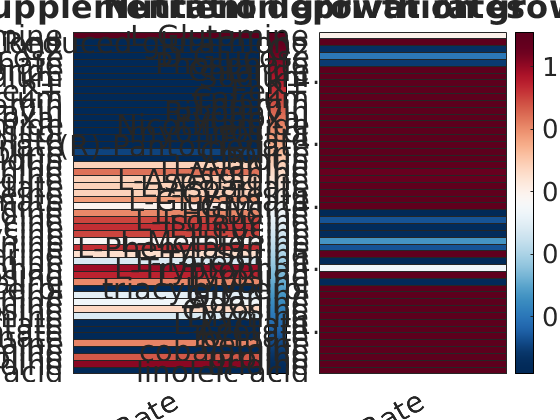

figure;
% Nutrient supplementation heatmap
subplot(1, 2, 1);
heatmap(supplementation_grate(:, 1), ...
        'YData', medium, ...
        'XData', ['Growth Rate'], ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient supplementation growth rates', ...
        'FontSize', 22, ...
        'FontName', 'Helvetica');

% Nutrient deprivation heatmap 
subplot(1, 2, 2);
heatmap(deprivation_grate(:, 1), ...
        'YData', medium, ...
        'XData', ['Growth Rate'], ...
        'Colormap', redbluecmap, ...
        'ylabel', 'Medium Components', ...
        'xlabel', 'Reactions', ...
        'title', 'Nutrient deprivation growth rates', ...
        'FontSize', 22, ...
        'FontName', 'Helvetica');